## FFT recursive

Recursion. The same trick is now applied to reduce the two DFTs of order n/2 to four DFTs of order n/4, see Figure 5.3. Four DFTs of order n/4 cost

In addition there are n/2 multiplications to recombine the results of the DFTs of order n/4 and n/2 multiplications to recombine the results of the DFTs of order n/2. 

The total effort is therefore n2/4 + n.

This process can be continued until it ends with DFTs or order n = 1, which is the case after ld(n) steps. 

As a DFT of order n = 1 costs nothing the only remaining costs are n/2 multiplications for the recombinations, i.e. in total 12

## 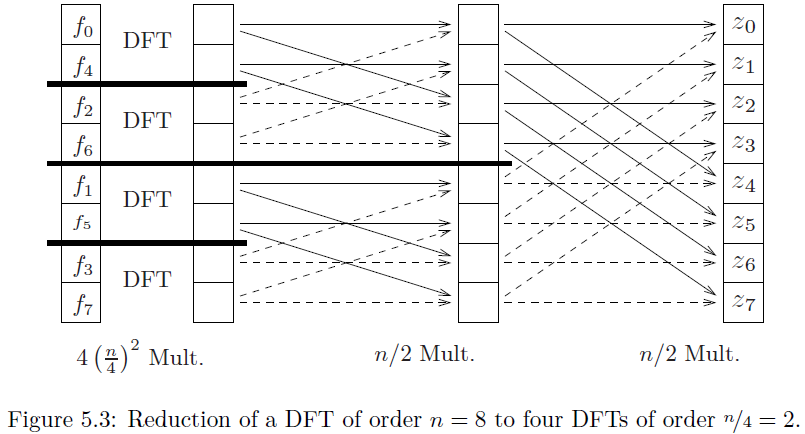

function [FFT_recursiv_signal_1, FFT_recursiv_signal_2] = recursive_fft(h1, h2)
    N = length(h1);
    
    if N <= 1  % End criteria
        FFT_recursiv_signal_1 = h1;
        FFT_recursiv_signal_2 = h2;
        return;
    end
    
    h1_even = h1(1:2:end);
    h1_odd = h1(2:2:end);
    h2_even = h2(1:2:end);
    h2_odd = h2(2:2:end);
    
    [FFT_even_1, FFT_even_2] = recursive_fft(h1_even, h2_even);
    [FFT_odd_1, FFT_odd_2] = recursive_fft(h1_odd, h2_odd);
    
    factor = exp(-2i * pi * (0:N/2-1) / N);
    FFT_recursiv_signal_1 = [FFT_even_1 + factor .* FFT_odd_1, FFT_even_1 - factor .* FFT_odd_1];
    FFT_recursiv_signal_2 = [FFT_even_2 + factor .* FFT_odd_2, FFT_even_2 - factor .* FFT_odd_2];
end

time_FFT_recursiv = tic; % Several times to get a more stable time output
FFT_iterations = 100;
for i = 1:FFT_iterations
    [FFT_recursiv_signal_1, FFT_recursiv_signal_2] = recursive_fft(h1, h2);
end
time_FFT_recursiv = toc(time_FFT_recursiv)/FFT_iterations

time_FFT_recursiv = 0.1880

#### Shift the end of the signal to the beginning

N=length(h1);
N_half=N/2;

shifted_FFT_recursiv_signal_1 = [FFT_recursiv_signal_1(N_half+1:end), FFT_recursiv_signal_1(1:N_half)];
shifted_FFT_recursiv_signal_2 = [FFT_recursiv_signal_2(N_half+1:end), FFT_recursiv_signal_2(1:N_half)];


shifted_FFT_recursiv_signal_1_magnitude = 1/N*abs(shifted_FFT_recursiv_signal_1);
shifted_FFT_recursiv_signal_2_magnitude = 1/N*abs(shifted_FFT_recursiv_signal_2);

% Frequency axis
k=1:N;                                          
f=(k-1)*(1/(N*ts));                   
f_c=f-((N-mod(N,2))/2)*(1/(N*ts));     

#### Plot the DFT, recursive FFT and Matlab calculated FFT

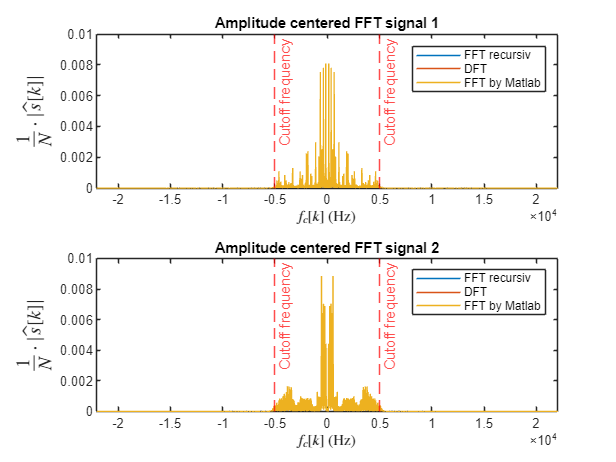

figure;
tiledlayout(2,1)
nexttile
plot(f_c, shifted_FFT_recursiv_signal_1_magnitude );
hold on
plot(f_c, shifted_DFT_signal_1_magnitude);
plot(f_c,FFT_signal_1_ampl_Matlab)
xline(-cutoff_f,LineStyle="--",Color='red',Label='Cutoff frequency')
xline(cutoff_f,LineStyle="--",Color='red',Label='Cutoff frequency')
hold off
title('Amplitude centered FFT signal 1');
xlabel('$f_c[k]$ (Hz)','Interpreter','Latex')
ylabel('$\frac{1}{N} \cdot |\hat{s}[k]|$','Interpreter','Latex', 'FontSize', 13)
legend('FFT recursiv','DFT','FFT by Matlab')
xlim([min(f_c) max(f_c)])

nexttile
plot(f_c,shifted_FFT_recursiv_signal_2_magnitude);
hold on
plot(f_c, shifted_DFT_signal_2_magnitude);
plot(f_c,FFT_signal_2_ampl_Matlab)
xline(-cutoff_f,LineStyle="--",Color='red',Label='Cutoff frequency')
xline(cutoff_f,LineStyle="--",Color='red',Label='Cutoff frequency')
hold off
title('Amplitude centered FFT signal 2');
xlabel('$f_c[k]$ (Hz)','Interpreter','Latex')
ylabel('$\frac{1}{N} \cdot |\hat{s}[k]|$','Interpreter','Latex', 'FontSize', 13)
legend('FFT recursiv','DFT','FFT by Matlab')
xlim([min(f_c) max(f_c)])

#### iFFT

function [iFFT_recursiv_signal_1, iFFT_recursiv_signal_2] = recursive_ifft(FFT_signal_1, FFT_signal_2)
    N = length(FFT_signal_1);
    
    if N <= 1  % End criteria
        iFFT_recursiv_signal_1 = FFT_signal_1;
        iFFT_recursiv_signal_2 = FFT_signal_2;
        return;
    end

    FFT_1_even = FFT_signal_1(1:2:end);
    FFT_1_odd = FFT_signal_1(2:2:end);
    FFT_2_even = FFT_signal_2(1:2:end);
    FFT_2_odd = FFT_signal_2(2:2:end);
    
    [iFFT_even_1, iFFT_even_2] = recursive_ifft(FFT_1_even, FFT_2_even);
    [iFFT_odd_1, iFFT_odd_2] = recursive_ifft(FFT_1_odd, FFT_2_odd);
    
    factor = exp(2i * pi * (0:N/2-1) / N);
    iFFT_recursiv_signal_1 = [iFFT_even_1 + factor .* iFFT_odd_1, iFFT_even_1 - factor .* iFFT_odd_1];
    iFFT_recursiv_signal_2 = [iFFT_even_2 + factor .* iFFT_odd_2, iFFT_even_2 - factor .* iFFT_odd_2];
end

[iFFT_recursiv_signal_1, iFFT_recursiv_signal_2] = recursive_ifft(FFT_recursiv_signal_1, FFT_recursiv_signal_2);

N = length(iFFT_recursiv_signal_1);
iFFT_recursiv_signal_1 = iFFT_recursiv_signal_1 / N;
iFFT_recursiv_signal_2 = iFFT_recursiv_signal_2 / N;

#### Plot the iFFT and compare with the lowpassfiltered signal

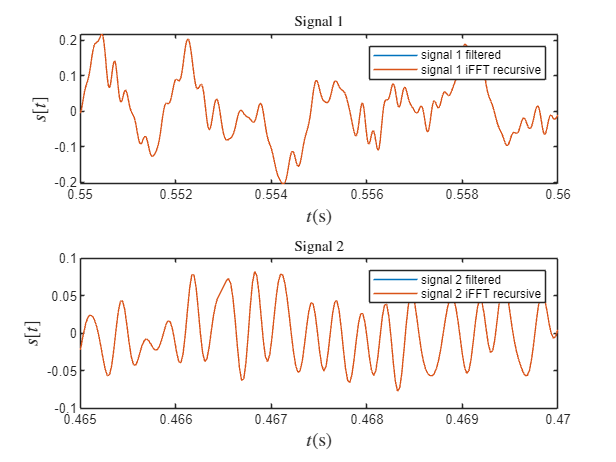

figure()
tiledlayout(2,1);
nexttile
plot(t,h1)
hold on
plot(t,real(iFFT_recursiv_signal_1))
hold off
title('Signal 1','Interpreter','Latex')
xlabel('$t$(s)','Interpreter','Latex', 'FontSize', 13)
ylabel('$s[t]$', 'Interpreter', 'latex', 'FontSize', 13);
legend('Signal 1 lowpass filtered','Signal 1 iFFT recursive')
xlim([0.55 0.56])%xlim([0 max(t)])

nexttile
plot(t,h2)
hold on
plot(t,real(iFFT_recursiv_signal_2))
hold off
title('Signal 2','Interpreter','Latex')
xlabel('$t$(s)','Interpreter','Latex', 'FontSize', 13)
ylabel('$s[t]$', 'Interpreter', 'latex', 'FontSize', 13);
legend('Signal 2 lowpass filtered','Signal 2 iFFT recursive')
xlim([0.465 0.47])%xlim([0 max(t)])

disp(['Comparison lowpassfiltered signal 1 and iFFT recursive signal 1 // Difference = ' num2str(sum(h1-real(iFFT_recursiv_signal_1)))])

Comparison lowpassfiltered signal 1 and iFFT recursive signal 1 // Difference = -2.6252e-15


disp(['Comparison lowpassfiltered signal 2 and iFFT recursive signal 2 // Difference = ' num2str(sum(h2-real(iFFT_recursiv_signal_2)))])

Comparison lowpassfiltered signal 2 and iFFT recursive signal 2 // Difference = -3.2495e-15
